We look at the balance between the axial spring and the magnet to lock the claw in position axially

clear
clf

considering a constant spring constant we get the pull of one **axial spring** from SODEMANN

% k_axial = 0.29e3; % N/mm --> N/m % max kraft 47,43, max vandring 140,97, total lenth 229,87
% % varenummer 	E07500633500S trækfjeder SODEMANN
% x_axial = 140e-3; % udspændt fjeder til træk af claw

k_axial = 0.65e3; % N/mm --> N/m % max kraft 56,94, max vandring 77,72, total lenth 141,22 L0 = 63,50
% E07500632500M	 % varenummer trækfjeder SODEMANN
x_axial = 70e-3; % udspændt fjeder til træk af claw
F_spring_axial = k_axial * x_axial

F_spring_axial = 45.5000

Frication acting on the calw is devided in to two kinds that are added up.

- Due to gravity we find

g = 9.82;
m_claw = 14.8; %kg <--------- differ between claws
f_s = 0.20; %static / kinetic friction coeffecient %steel on steel
F_claw_fric = g * m_claw * f_s

F_claw_fric = 29.0672

We sum the forces and add them

syms F_n_x
F_n_x_eq = 0 == F_spring_axial - F_claw_fric + F_n_x;

F_n_x_sol = solve(F_n_x_eq, F_n_x);
F_n_x_sol = double(F_n_x_sol)

F_n_x_sol = -16.4328

## plot

% syms F_n_x
% x_slut = 1e-3;
% xs = x_contact:2e-5:x_slut; %Distance between magnets
% for i = 1:length(xs)  
% 
%     x_axial = 140e-3 - xs(i); % udspændt fjeder til træk af claw
%     F_spring_axial = k_axial * x_axial;
% 
%     F_n_x_eq = 0 == F_spring_axial - F_magnet - F_claw_fric + F_n_x;
%     F_n_x_sol = solve(F_n_x_eq, F_n_x);
% 
%     F_n_x_sols(i) = double(F_n_x_sol);
%     F_magnets(i) = F_magnet; % for later use
% end
% 
% plot(xs*1000, F_n_x_sols, DisplayName="force needed to unlock")
% hold on
% 
% xline(x_contact*1000,'r--', DisplayName="start location of magnet")
% yline(0,'--', DisplayName="Release happens below")
% xlabel("Distance between magnets - $x [mm]$", Interpreter="latex")
% ylabel("Force requred to release - F_{n,x}[N]")
% grid("minor")
% legend(location='best')
% hold off

**Release force**

n_stack = 3; %number of stacked disc springs for more force
F_realese = 553 * n_stack; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s = 0.53e-3;
% tallerken fjeder vare nummer 1800-620-70

% T = F_realese * r
W = F_realese * s % The work the spring does on the rotor

W = 0.8793


syms omega
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-2
I = 15.9356; % inertia of the test motor % HMC4 355L-2 <--------- differ from motor to motor
W_eq = W == 1/2 * I * omega^2; % work of the rotor
omega_sol = solve(W_eq, omega);
omega = double(omega_sol(2))

omega = 0.3322

Dermed har jeg hastigheden ved slip, kraften aftager løbende i fjederen men antage at være tæt på F_realease_x i det kontakten slippes.

Couplings delen skal rejse 1 mm og tabet her negligeres

F_fric = F_spring_axial * f_s

F_fric = 9.1000


double(omega_sol(2))

ans = 0.3322

r_outer = 0.066;

phi_tab = 8; % arc of tab
s_fric = 2*pi*r_outer * phi_tab/360

s_fric = 0.0092

W_fric = F_fric *2 * s_fric

W_fric = 0.1677


energi_left = W - W_fric

energi_left = 0.7116


syms omega
W_eq = 1/2 * I * omega^2 ==  W - W_fric;
sol = solve(W_eq,omega);
sol_omega = double(sol(2))

sol_omega = 0.2988


t = 1; %sek
s = sol_omega*r_outer*t

s = 0.0197

Torque area - Falde tryk

% A = 1593 * 2; %mm^2
r_outer = 0.066

r_outer = 0.0660

A = 574 * 2; %mm^2
T = 10e3;
S = T/r_outer / A

S = 131.9818

Aksel for dimentionering

 ved flydnign

T_max = 10e3; %Nm
% d = 95e-3; %mm
n_y = 2; %drev Kraftige stød % arbejds maskinen Lette stød
S_y = 375; %375 - 460 % edu pack C45 - AISI 1040

% tau_max_Pa = T_max / (pi/16 * d^3) 
% ta_max_MPa = tau_max_Pa/1e6
tau_til = 1/sqrt(3) * S_y / n_y

tau_til = 108.2532


d_m = (T_max / (pi/16  * tau_til * 1e6))^(1/3)

d_m = 0.0778

d_mm = d_m * 1000

d_mm = 77.7756

Spline

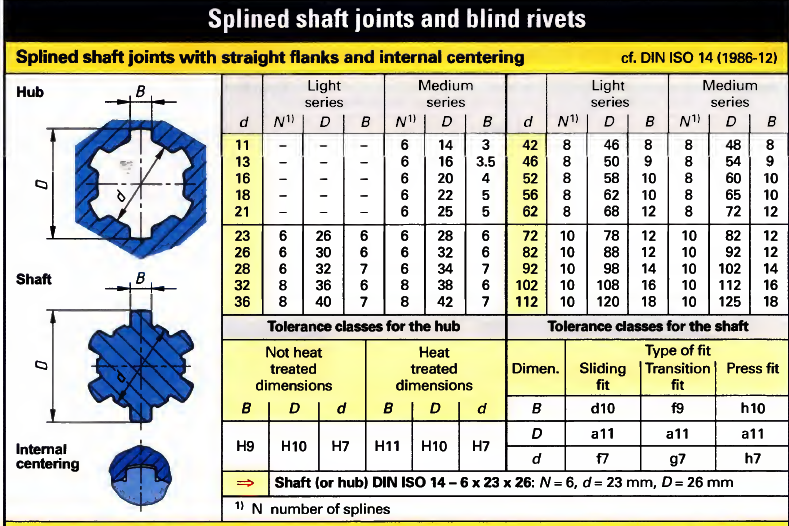

d = 82e-3; % d>77,8 see above %shaft diameter
N = 10; %number of theeth
% D = 92e-3; %medium series outer diameter
D = 88e-3; %light series outer diameter
B = 12; %width of tooth

L = 75e-3;%length of spline interacion
r = (D/2 - (D-d)/2)

r = 0.0410

F = T_max / r

F = 2.4390e+05

A = (D-d)/2 * L %areal i kontakt pr spline

A = 2.2500e-04

S_Pa = F / (A* N)

S_Pa = 1.0840e+08

S_MPA =S_Pa /1e6

S_MPA = 108.4011

Spline holds on Light series

DIN 5480-16 2006

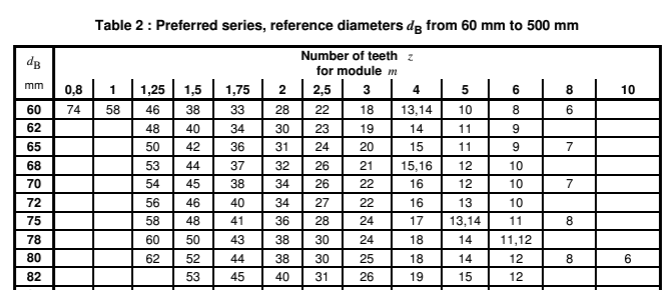

% d_B

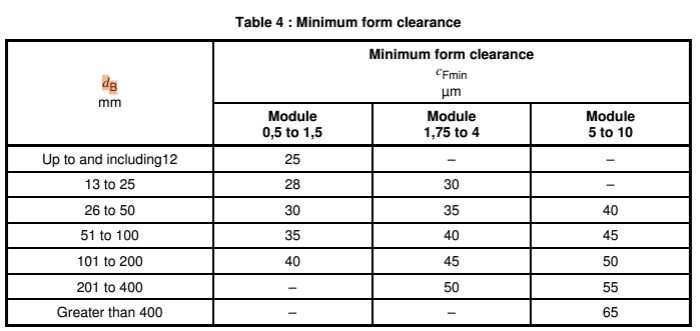

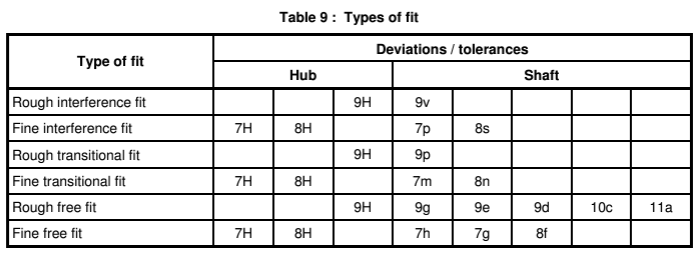

shaft 9e

hub 9H

se side 103 i den blå